# testing kmeans_sdp_pengwei

dfdf

% Load or create your 2-cluster data
rng(1);
X = [randn(50,2)*0.75 + [2 2]; randn(50,2)*0.5 + [-2 -2]];
n = size(X,1);
k = 2;

% Build Gaussian kernel affinity matrix
sigma = 1.0;
A = exp(-pdist2(X, X).^2 / (2*sigma^2));

% Run Peng-Wei SDP k-means
Z = kmeans_sdp_pengwei(A, k);

  breakyes = 1.0,  maxresidual < 1.00e-04  breakyes=1.0,  maxresidual < 1.00e-06

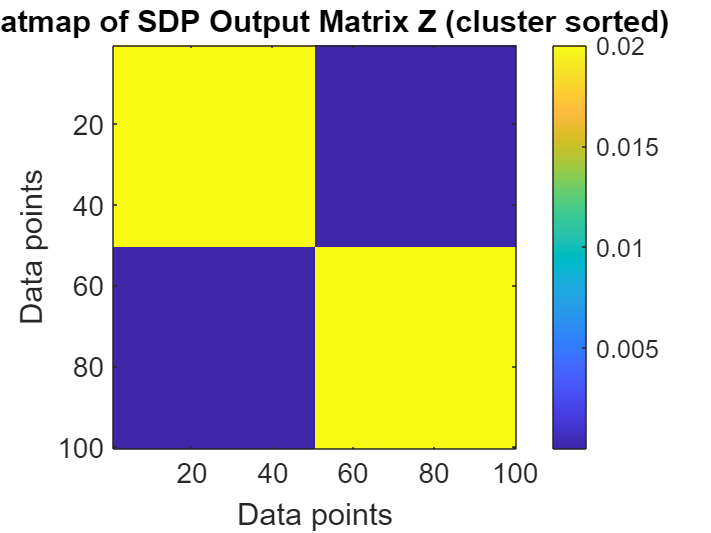


% Extract clustering: use k-means on top eigenvectors
[U,~,~] = svd(Z); 
U_k = U(:,1:k);  % top-k eigenvectors
clusters = kmeans(U_k, k, 'Replicates', 10);

% Visualization: Heatmap of Z with cluster ordering
[~, sort_idx] = sort(clusters);       % sort points by cluster
Z_sorted = Z(sort_idx, sort_idx);     % reorder rows/cols

figure;
imagesc(Z_sorted);
colorbar;
title('Heatmap of SDP Output Matrix Z (cluster sorted)');
xlabel('Data points');
ylabel('Data points');
axis square;

# Initialization

## test for cluster_spectral

% Test script for cluster_spectral

% Parameters
n_per_cluster = 50;
k = 3;
d = 2;
rng(42); % For reproducibility

% Generate synthetic data: 3 Gaussian blobs
centers = [0 0; 5 5; 10 0];
x = [];
for i = 1:k
    x = [x; randn(n_per_cluster, d) + centers(i,:)]; %#ok<AGROW>
end
x = x'; % Convert to d x n (as expected by cluster_spectral)

% Run spectral clustering
cluster_est = cluster_spectral(x, k);

% Basic checks
assert(isvector(cluster_est), 'Output must be a vector');
assert(length(cluster_est) == k * n_per_cluster, 'Incorrect number of cluster assignments');
assert(numel(unique(cluster_est)) == k, 'Should find exactly k clusters');

fprintf('Test passed: cluster_spectral produced %d clusters on synthetic data.\n', k);

Test passed: cluster_spectral produced 3 clusters on synthetic data.


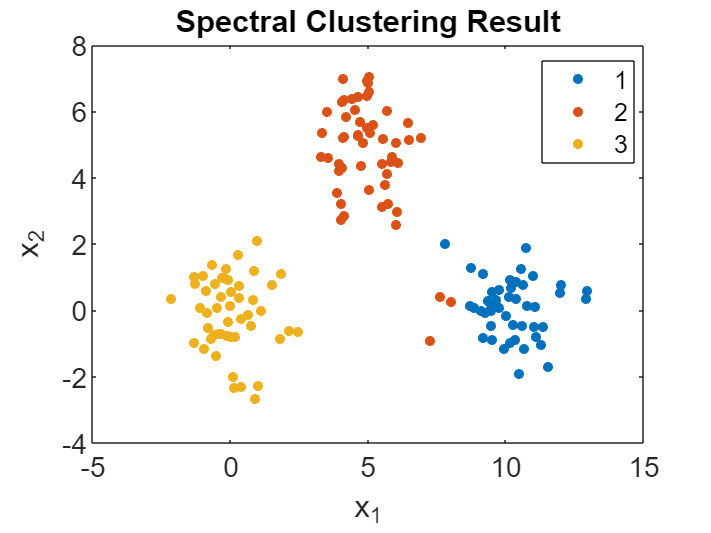


% Optional: plot the result
figure;
gscatter(x(1,:), x(2,:), cluster_est);
title('Spectral Clustering Result');
xlabel('x_1'); ylabel('x_2');

# Variable selection

## testing ISEE_bicluster

% Parameters
p = 2000;   % Number of features (even)
n = 500;  % Total samples
n1 = n / 2; n2 = n - n1;

% Means for two clusters
mu1 = zeros(p, 1);
mu2 = [ones(p/2,1); -ones(p/2,1)];

% Shared covariance matrix (AR(1) structure)
rho = 0.5;
Sigma = toeplitz(rho.^(0:(p-1)));
Omega = inv(Sigma); % True precision matrix
Omega_diag_true = diag(Omega);

% Generate Gaussian data with shared covariance
x1 = mvnrnd(mu1, Sigma, n1)'; % size p x n1
x2 = mvnrnd(mu2, Sigma, n2)'; % size p x n2
x = [x1, x2];

% Cluster assignments
cluster_est_now = [ones(1, n1), 2 * ones(1, n2)];

% Run your bicluster method
[mean_now, noise_now, Omega_diag_hat] = ISEE_bicluster(x, cluster_est_now);

% Compare estimated vs true diagonals
Omega_diag_est = Omega_diag_hat; % already p x 1

% Compute mean squared error (MSE)
mse = mean((Omega_diag_est - Omega_diag_true).^2);

fprintf('MSE of diagonal precision estimate (shared covariance): %.4f\n', mse);

MSE of diagonal precision estimate (shared covariance): 0.0194


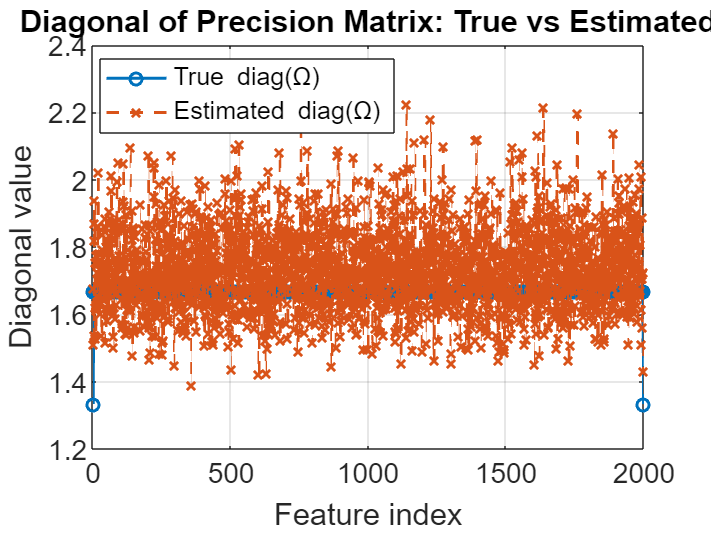


% Plot true vs estimated diagonals
figure;
plot(Omega_diag_true, '-o', 'LineWidth', 1.5); hold on;
plot(Omega_diag_est, '--x', 'LineWidth', 1.5);
legend('True diag(\Omega)', 'Estimated diag(\Omega)', 'Location', 'Best');
xlabel('Feature index'); ylabel('Diagonal value');
title('Diagonal of Precision Matrix: True vs Estimated');
grid on;

### Implementation of the stopping criteria

#### K means objective function

%function objective_value_original = get_objective_value_original(x, cluster_est)
   %     objective_value_original = 0;
  %      for i = 1:ik.data_object.number_cluster
  %          cluster_size = sum(cluster_est==i);
 %          affinity_cluster = ik.data_object.sparse_affinity(cluster_est==i, cluster_est==i);
 %           within_cluster_variation = ((-2*sum(affinity_cluster, "all") + 2*cluster_size*trace(affinity_cluster))/cluster_size;
 %           objective_value_original = objective_value_original + within_cluster_variation;
 %       end

   % end